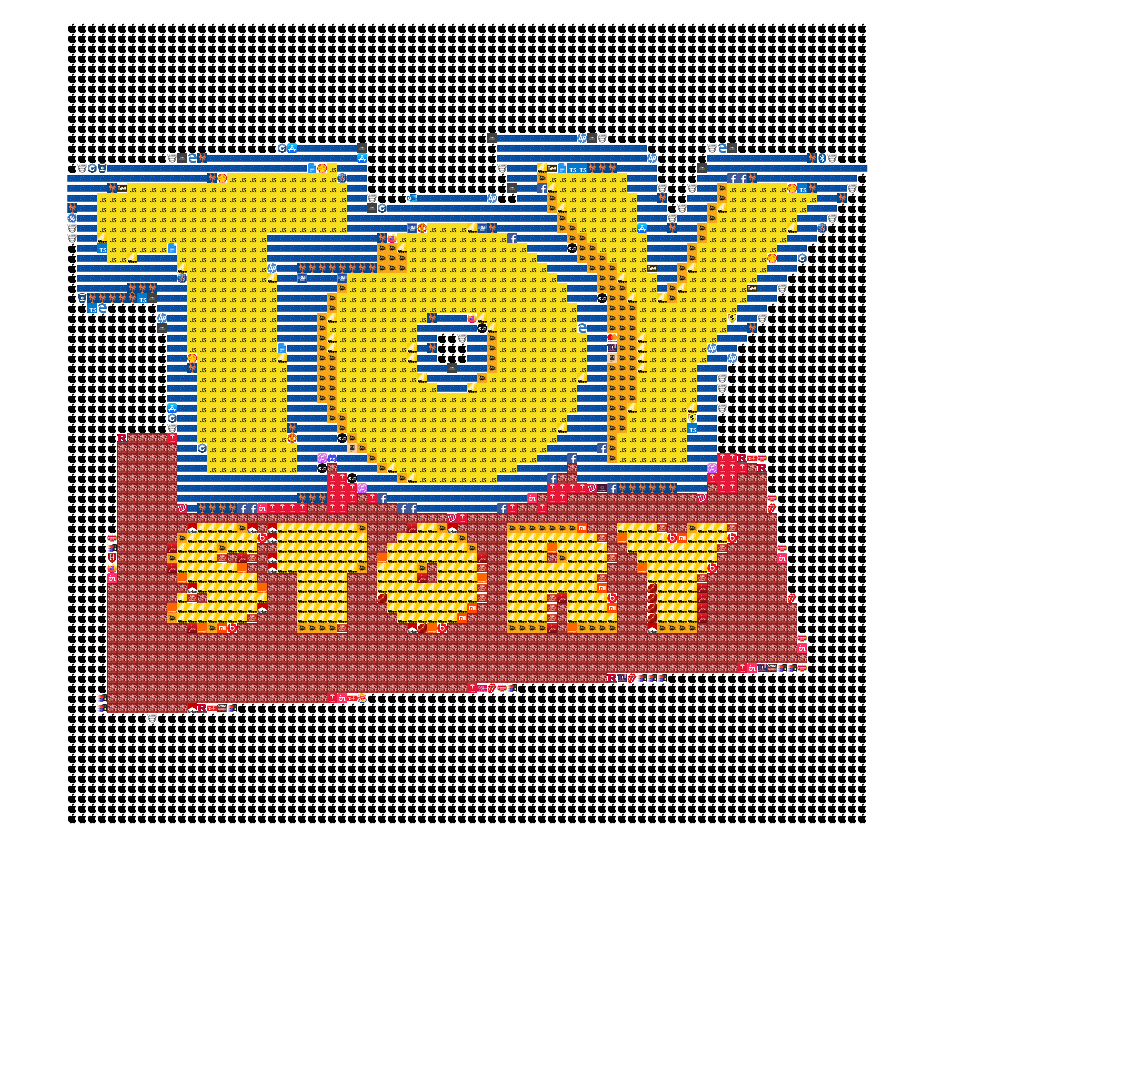

clear
clf

dataBase = cell(200, 1);

for i = 1:200
    dataBase{i} = imread(['Database_logos/' int2str(i) '.jpg']);
end

save dataBase dataBase

load dataBase.mat

numImages = numel(dataBase);

targetSize = [50, 50]; % -------------------Target size

for i = 1:numImages
    currentImage = dataBase{i};
    resizedImage = imresize(currentImage, targetSize);
    dataBase{i} = resizedImage;
end

save dataBase dataBase;

load dataBase

colorBase = cell(200, 1);

for i = 1:200
    
    currentImage = dataBase{i};
    
    labImage = rgb2lab(currentImage);
    
    L = labImage(:, :, 1);
    a = labImage(:, :, 2);
    b = labImage(:, :, 3);
    
    colorBase{i} = struct('L', L, 'a', a, 'b', b);
end

save colorBase colorBase

queryImage = imread("Database_logos/41.jpg"); % Logos 
%queryImage = imread("Images/db1_01.jpg"); % Faces
%queryImage = imread("Images/night.jpg"); % Starry Night
hold on


queryImage = imresize(queryImage, [2000, 2000]);

queryImageLab = rgb2lab(queryImage);

QueryColorBase = cell(1, 1);
 
queryImageL = sum(sum(queryImageLab(:,:,1))); 
queryImagea = sum(sum(queryImageLab(:,:,2))); 
queryImageb = sum(sum(queryImageLab(:,:,3))); 
    
QueryColorBase{1} = struct('L', queryImageL, 'a', queryImagea, 'b', queryImageb);

save QueryColorBase QueryColorBase

load dataBase.mat
load colorBase.mat
load QueryColorBase.mat 

ActiveImages = cell(200,1);

gridSize = 25; % ---------------- GRID SIZE -------------------

numRows = size(queryImageLab, 1) / gridSize;
numCols = size(queryImageLab, 2) / gridSize;

QueryColorDominating = 'a'; 

for i = 1:numRows
    for j = 1:numCols
        % Dominating color in each region
        replaceRegionRows = (i-1)*gridSize+1 : i*gridSize;
        replaceRegionCols = (j-1)*gridSize+1 : j*gridSize;
        
        % Ensure indices are within image dimensions
        replaceRegionRows = min(max(replaceRegionRows, 1), size(queryImageLab, 1));
        replaceRegionCols = min(max(replaceRegionCols, 1), size(queryImageLab, 2));
        
        LChannel = queryImageLab(replaceRegionRows, replaceRegionCols, 1);
        aChannel = queryImageLab(replaceRegionRows, replaceRegionCols, 2);
        bChannel = queryImageLab(replaceRegionRows, replaceRegionCols, 3);
        
        % Use median instead of mean
        currentColor = [median(LChannel(:)), median(aChannel(:)), median(bChannel(:))];
        
        % Normalize the entire LAB vector
        currentColor = currentColor / norm(currentColor);
        
        currentDiff = inf;
        bestMatchIndex = 1; 
        
        % Calculate Euclidean distance for each image
        for q = 1:200
            targetColor = [median(colorBase{q}.L(:)), median(colorBase{q}.a(:)), median(colorBase{q}.b(:))];
            
            % Normalize the entire LAB vector
            targetColor = targetColor / norm(targetColor);
            
            distance = norm(currentColor - targetColor);
            
            if distance < currentDiff
                bestMatchIndex = q;
                currentDiff = distance;
            end   
        end

        resizedColorInfo = imresize(colorBase{bestMatchIndex}.L, [numel(replaceRegionRows), numel(replaceRegionCols)]);
        queryImageLab(replaceRegionRows, replaceRegionCols, 1) = resizedColorInfo;
        
        resizedColorInfo = imresize(colorBase{bestMatchIndex}.a, [numel(replaceRegionRows), numel(replaceRegionCols)]);
        queryImageLab(replaceRegionRows, replaceRegionCols, 2) = resizedColorInfo;
        
        resizedColorInfo = imresize(colorBase{bestMatchIndex}.b, [numel(replaceRegionRows), numel(replaceRegionCols)]);
        queryImageLab(replaceRegionRows, replaceRegionCols, 3) = resizedColorInfo;


    end
end

rgbImage = lab2rgb(queryImageLab); 
imshow(rgbImage)